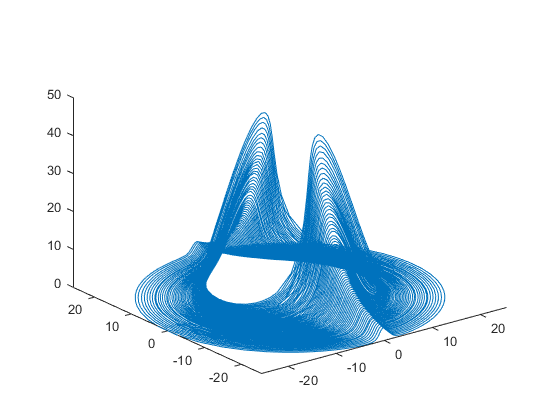

% STARTING PARAMETERS
% a(1) = x ; a(2) = y; a(3) = z
alfa = 0.2715;
gama = 0.1;
t_max = 10;

% 3D SYSTEM PLOT
f = @(t,a) [a(2)*(a(3)-1+a(1)^2)+gama*a(1); a(1)*(3*a(3)+1-a(1)^2)+gama*a(2); -2*a(3)*(alfa+a(1)*a(2))];
[t,a] = ode45(f,[0 t_max],[10 10 10]);     % Runge-Kutta 4th/5th order ODE solver
plot3(a(:,1),a(:,2),a(:,3))

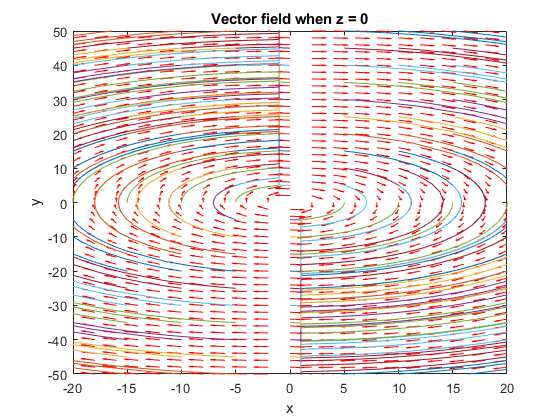


% 2D PLOTS ON DIFFERENT PLANES
% XOY then z=0
z=0;
sys=@(t,x) [x(2)*(z-1+x(1)^2)+gama*x(1); x(1)*(3*z+1-x(1)^2)+gama*x(2); -2*z*(alfa+x(1)*x(2))];
figure(1)
vectorfield(sys,-20:2:20,-50:2:50);
hold on
sep=5;
for x0=-20:sep:20
for y0=-50:sep:50
[ts,xs] = ode45(sys,[0 t_max],[x0 y0 0]);
plot(xs(:,1),xs(:,2))
title('Vector field when z = 0');
xlabel('x');
ylabel('y');
end
end
axis([-20 20 -50 50]);
hold off

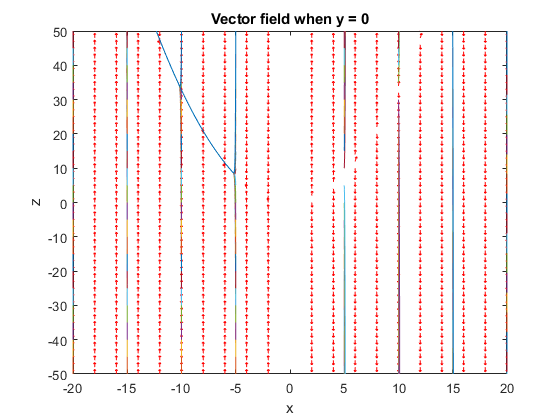


% XOZ then y=0
y=0;
sys=@(t,x) [y*(x(2)-1+x(1)^2)+gama*x(1); x(1)*(3*x(2)+1-x(1)^2)+gama*y; -2*x(2)*(alfa+x(1)*y)];
figure(1)
vectorfield(sys,-20:2:20,-50:2:50);
hold on
sep=5;
for x0=-20:sep:20
for z0=-50:sep:50
[ts,xs] = ode45(sys,[0 t_max],[x0 z0 0]);
plot(xs(:,1),xs(:,2))
title('Vector field when y = 0');
xlabel('x');
ylabel('z');
end
end
axis([-20 20 -50 50]);
hold off



% YOZ then x=0
xx=0;

sys=@(t,x) [x(1)*(x(2)-1+xx^2)+gama*xx; xx*(3*x(2)+1-xx^2)+gama*x(1); -2*x(2)*(alfa+xx*x(1))];
figure(1)
vectorfield(sys,-20:2:20,-50:2:50);
hold on
sep=5;
for y0=-20:sep:20
for z0=-50:sep:50
[ts,xs] = ode45(sys,[0 t_max],[y0 z0 0]);
plot(xs(:,1),xs(:,2))
title('Vector field when x = 0');
xlabel('y');
ylabel('z');
end
end

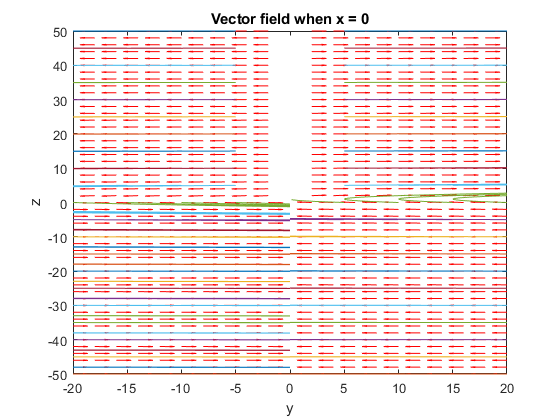

axis([-20 20 -50 50]);
hold off



% LYAPUNOV EXPONENT CALCULATION
syms l
A = [0.1 -1 0 ; 1 0.1 0; 0 0 -0.543]

A =     0.1000   -1.0000         0
    1.0000    0.1000         0
         0         0   -0.5430


eig(A)

ans =    0.1000 + 1.0000i
   0.1000 - 1.0000i
  -0.5430 + 0.0000i



A = [0.1 -1 0 ; 1 0.1 0; 0 0 -0.543]

A =     0.1000   -1.0000         0
    1.0000    0.1000         0
         0         0   -0.5430


P = lyap(A, eye(3))

P =    -5.0000   -0.0000         0
   -0.0000   -5.0000         0
         0         0    0.9208



% V MATRIX CALCULATION
syms x y z
V = [x y z]*P*[x; y; z]

$$V = \frac{500\,z^{2}}{543}-x\,\left(5\,x+\frac{3\,y}{18014398509481984}\right)-y\,\left(\frac{3\,x}{18014398509481984}+5\,y\right)$$

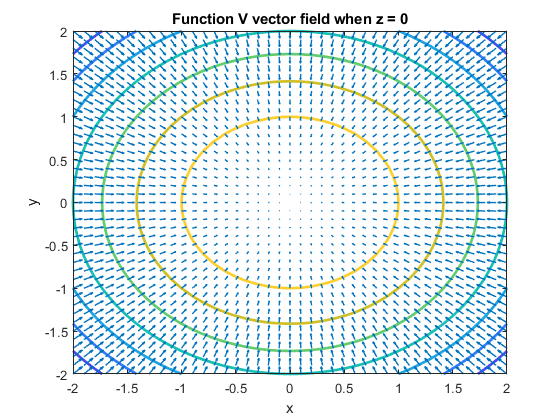


% 2D AND 3D VECTORFIELD CALCULATION
clc;
u = -2:0.1:2;
Z=0;
[X,Y] = meshgrid(u);
V = (500/543)*Z.^2-X.*(5*X-(3/18014398509481984)*Y)-Y.*((3/18014398509481984)*X+5*Y);
[px,py] = gradient(V,.2,.2);
figure(1)
contour(u,u,V,'linewidth',2)
hold on
quiver(u,u,px,py,'linewidth',1)
hold off
title(['Function V vector field when z = ',num2str(Z)]);
xlabel('x');
ylabel('y');

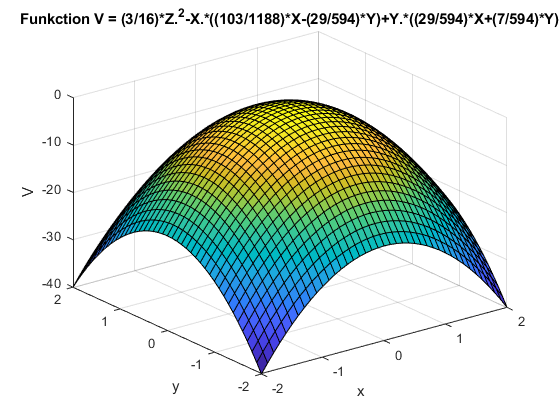

figure(2)
surf(X,Y,V);
xlabel('x');
ylabel('y');
zlabel('V');
title('Funkction V = (3/16)*Z.^2-X.*((103/1188)*X-(29/594)*Y)+Y.*((29/594)*X+(7/594)*Y)');

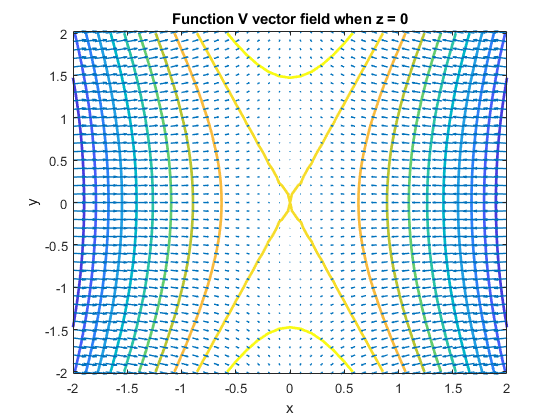



clc;
u = -2:0.1:2;
Y=0;
[X,Z] = meshgrid(u);
V = (500/543)*Z.^2-X.*(5*X-(3/18014398509481984)*Y)-Y.*((3/18014398509481984)*X+5*Y);
[px,py] = gradient(V,.2,.2);
figure(1)
contour(u,u,V,'linewidth',2)
hold on
quiver(u,u,px,py,'linewidth',1)
hold off
title(['Function V vector field when z = ',num2str(Y)]);
xlabel('x');
ylabel('y');

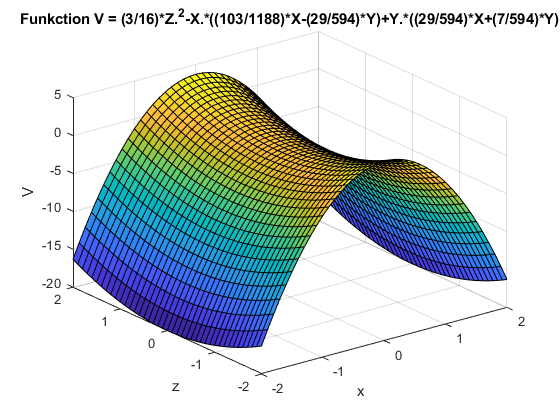

% axis equal;
figure(2)
surf(X,Z,V);
xlabel('x');
ylabel('z');
zlabel('V');
title('Funkction V = (3/16)*Z.^2-X.*((103/1188)*X-(29/594)*Y)+Y.*((29/594)*X+(7/594)*Y)');

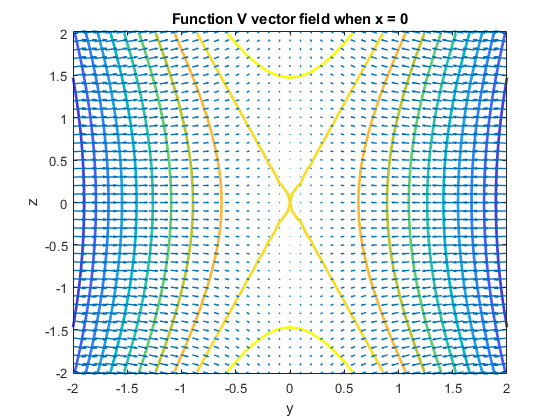



clc;
u = -2:0.1:2;
X=0;
[Y,Z] = meshgrid(u);
V = (500/543)*Z.^2-X.*(5*X-(3/18014398509481984)*Y)-Y.*((3/18014398509481984)*X+5*Y);
[px,py] = gradient(V,.2,.2);
figure(1)
contour(u,u,V,'linewidth',2)
hold on
quiver(u,u,px,py,'linewidth',1)
hold off
title(['Function V vector field when x = ',num2str(X)]);
xlabel('y');
ylabel('z');

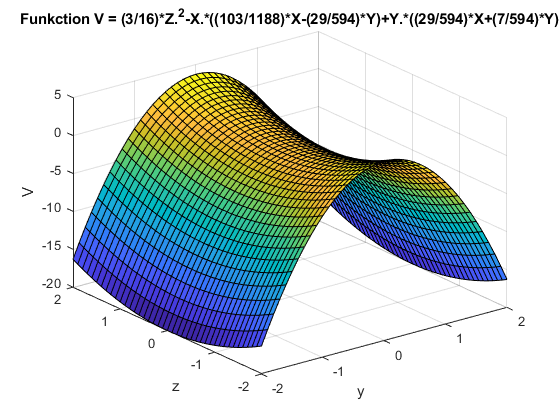

% axis equal;
figure(2)
surf(Y,Z,V);
xlabel('y');
ylabel('z');
zlabel('V');
title('Funkction V = (3/16)*Z.^2-X.*((103/1188)*X-(29/594)*Y)+Y.*((29/594)*X+(7/594)*Y)');



clc;
[T,Res]=lyapunov(3,@lorenz_ext,@ode45,0,0.01,50,[-0.05 0.05 1],10);

t=0.1000  10.069795 -21.069112  -2.667350
t=0.2000  10.934546 -21.914992  -2.686221
t=0.3000  11.185584 -21.594277  -3.257973
t=0.4000  11.317987 -18.327053  -6.657600
t=0.5000  11.399818 -15.236906  -9.829579
t=0.6000  11.433529 -13.129569 -11.970626
t=0.7000  11.259285 -11.523452 -13.402500
t=0.8000  10.184276 -10.001505 -13.849438
t=0.9000   8.327882  -9.016110 -12.978438
t=1.0000   6.374405  -8.053280 -11.987792
t=1.1000   4.834752  -7.206170 -11.295249
t=1.2000   4.249604  -6.697503 -11.218768
t=1.3000   4.031242  -6.247273 -11.450636
t=1.4000   3.635027  -5.675901 -11.625793
t=1.5000   3.437176  -5.375645 -11.728198
t=1.6000   3.218148  -5.068718 -11.816097
t=1.7000   2.910097  -4.642641 -11.934123
t=1.8000   2.820627  -4.408559 -12.078735
t=1.9000   2.793200  -4.244960 -12.214908
t=2.0000   2.593038  -3.952877 -12.306827
t=2.1000   2.472079  -3.788855 -12.349890
t=2.2000   2.376814  -3.663371 -12.380110
t=2.3000   2.188711  -3.419975 -12.435403
t=2.4000   2.112691  -3.259329 -12

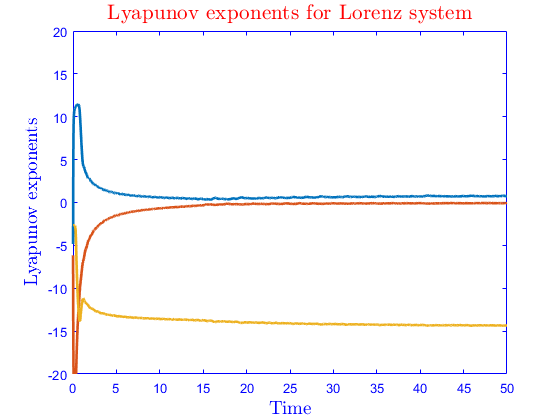

plot(T,Res,'LineWidth',2);
title('Lyapunov exponents for Lorenz system','Interpreter','latex','FontSize',16,'FontWeight','bold','Color','r');
xlabel('Time','Interpreter','latex','FontSize',14,'FontWeight','bold','Color','r');
ylabel('Lyapunov exponents','Interpreter','latex','FontSize',14,'FontWeight','bold','Color','r');
set(gca,'xcolor','b');
set(gca,'ycolor','b');
set(gca,'zcolor','b');
axis([0 50 -20 20])